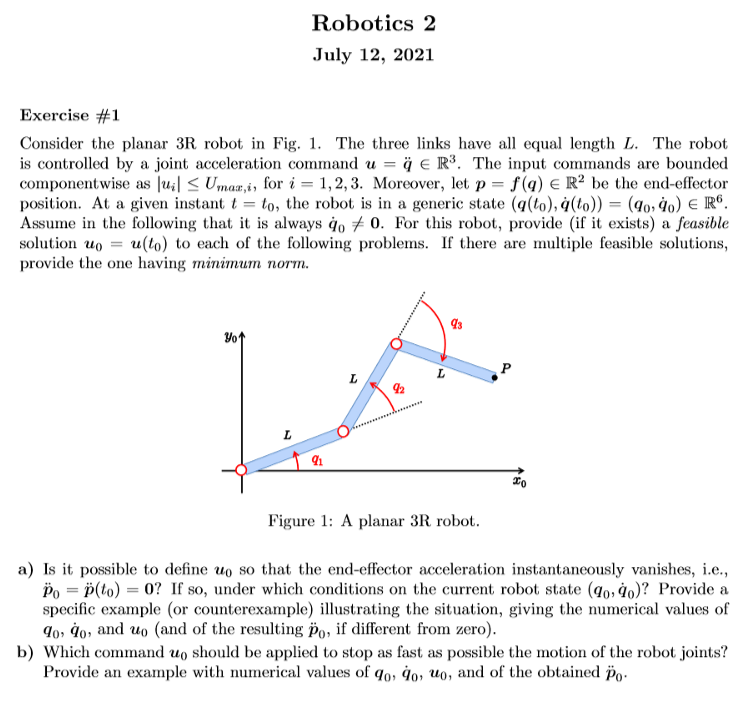

% % % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,0,0];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

% R2Robot=['rrr';'xxx';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% 
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% % % 
% % % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
% % % 

% % % 
% % % PC_EEShort.J
% % % PC_EEShort.f

% % % VarShortRobot.M
% % % angle_desired=[0,0]
% % % % xyonly=true
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z)

% PCVar.f_dot
% PC_EEShort.f
% PC_EEShort.J
% f
% J
% PC_EEShort.J_dot_short
% 

## defining Control output

% % lambda=sym('lambda','real')
% % a_sym=sym('a','real')
% % b_sym=sym('b','real')
% % u_sym=lambda*a_sym+b_sym
% % 
% % 

## U_max definition

% U_max=[15,10,10]'*pi
% q_=[0,pi/2,pi/2]'
% q_dot_=0.7*[pi,pi,0]'
% l_=[1,1,1]'
% to_replace=[z.q;z.q_dot;z.l]
% to_replace_=[q_;q_dot_;l_]

## Replacing values

% % J0_=subs(J,to_replace,to_replace_)
% % p0_=J0_*q_dot_
% % f0_fot_=subs(PCVar.f_dot,to_replace,to_replace_)
% % 
% % J0_dot_=subs(PC_EE.J_dot,to_replace,to_replace_)
% % J0_pinv_=pinv(J0_)
% % h0_=J0_dot_*q_dot_
% % 

## getting u

% % a_=-J0_pinv_*J0_*q_dot_
% % b_=-J0_pinv_*h0_
% % a_=vpa(a_)
% % b_=vpa(b_)
% % 
% % % with complete computations it follows manually
% 

## SNS algorithm case 1

% abs_on=true;
% autodetectsign=true
% J_=[-1,-1,0;0,1,1]
% h0_=[3;-4]*pi^2
% % [qdotstarFinal] = SNSMethod1(V_,J_,q_dMax_',abs_on,autodetectsign)
% 
% [qdotstarFinal,W] = SNSMethod2(h0_,J_,U_max*0,-U_max,U_max)%,Qdotmin,Qdotdmax)
% 
% vpa(qdotstarFinal)
% pd2_=vpa(J_)*qdotstarFinal
% vpa(norm(qdotstarFinal))

## SNS algorithm case 2

% abs_on=true;
% autodetectsign=true
% J_=sym([-1,-1,0;0,1,1])
% J_dot_=[7/4,11/4,11/4;-2,-2,0]*pi
% h0_=[105/16;-4]*pi^2
% [qdotstarFinal] = SNSMethod1(-h0_,J_,U_max,abs_on,autodetectsign)
% 
% % [qdotstarFinal,W] = SNSMethod2(h0_,J_,U_max*0,-U_max,U_max)%,Qdotmin,Qdotdmax)
% 
% vpa(qdotstarFinal)
% pd2_=vpa(J_)*qdotstarFinal
% vpa(norm(qdotstarFinal))

## Exercise 2

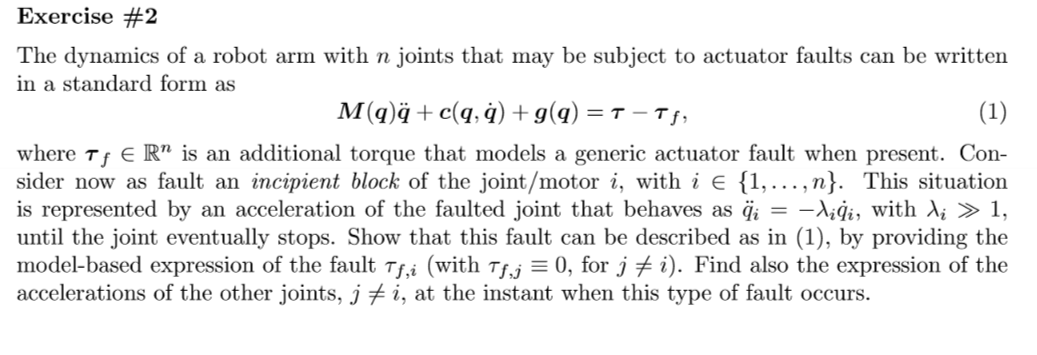

## Exercise 3

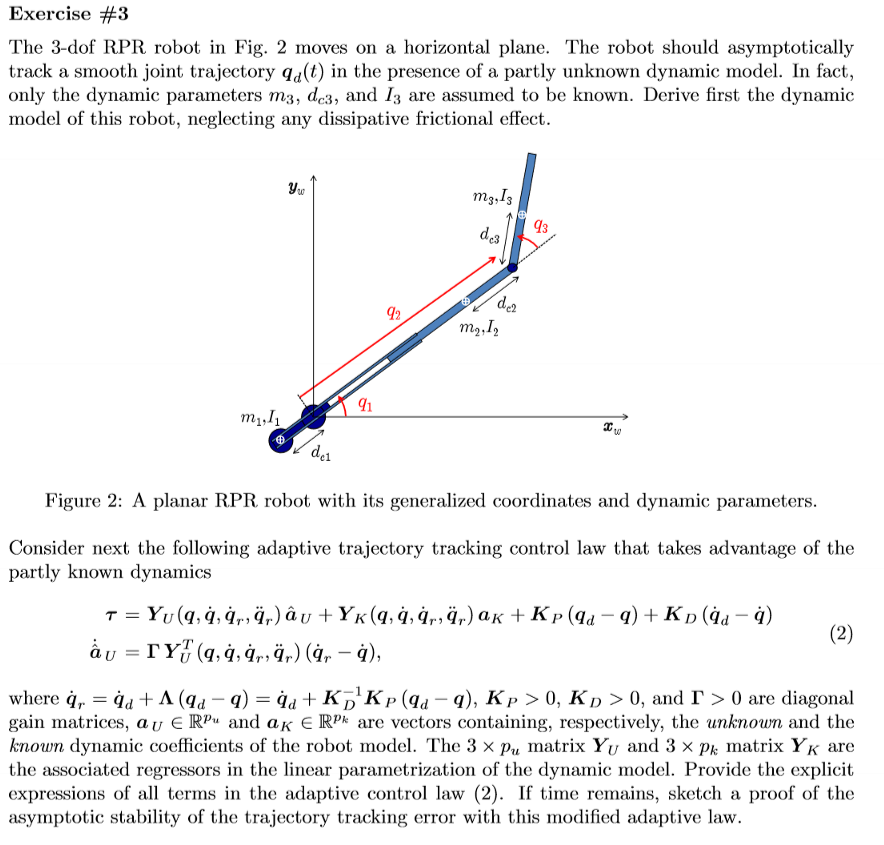


% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0,1,0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,-g0,0]';

R2Robot=['rpr';'xxx';sigmaD]

R2Robot = 3×3 char array
    'rpr'
    'xxx'
    '  '


z = Gen_param(n);
z.sigmaD=R2Robot;
% l(1)=0 %don't do this because dc1 is going to dissaperar
z.opt_expr={[l(1)],[0]};%use this instead
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 is

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));

% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 is

% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [1×3 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 is

si falla aquí está el error


$$a = l_{1}$$

d = 0

anglerot = 1×2 cell array
    {4×4 sym}    {4×4 sym}


$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,q_{2}+{q_{2}}^{2}\right)+{{\dot{q}}_{2}}^{2}+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+2\,q_{2}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\right)-2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(q_{3}\right)-2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)$$

$$To\_derive = \begin{array}{l} \left(\begin{array}{ccc} -\sigma_{1}-\sin\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \cos\left(q_{1}\left(t\right)\right) & -\sigma_{1}\\ \sigma_{2}+\cos\left(q_{1}\left(t\right)\right)\,q_{2}\left(t\right) & \sin\left(q_{1}\left(t\right)\right) & \sigma_{2}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{1}\left(t\right)+q_{3}\left(t\right)\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{1}\left(t\right)+q_{3}\left(t\right)\right) \end{array}$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×3 sym]


z_derivated = struct with fields:
     dot_t: [3×3 sym]
    ddot_t: [3×3 sym]


z_derivated = struct with fields:
     dot_t: [3×3 sym]
    ddot_t: [3×3 sym]
    tdot_t: [3×3 sym]


z_derivated = struct with fields:
        dot_t: [3×3 sym]
       ddot_t: [3×3 sym]
       tdot_t: [3×3 sym]
          dot: [3×3 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×3 sym]
       ddot_t: [3×3 sym]
       tdot_t: [3×3 sym]
          dot: [3×3 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []
          tdot: [3×3 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×3 sym]
        ddot_t: [3×3 sym]
        tdot_t: [3×3 sym]
           dot: [3×3 sym]
     dot_short: []
          ddot: [3×3 sym]
    ddot_short: []
          tdot: [3×3 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{ccc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & {\dot{q}}_{2}\,\cos\left(q_{1}\right)+{\dot{q}}_{1}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\dot{q}}_{2}\,\cos\left(q_{1}\right)-{\dot{q}}_{1}\,\left({\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sin\left(q_{1}+q_{3}\right)\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{2}\,\sin\left(q_{1}\right)-{\dot{q}}_{1}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{1}+q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{3} \end{array}\right)$$

$$T = \frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,q_{2}+{q_{2}}^{2}\right)+{{\dot{q}}_{2}}^{2}+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+2\,q_{2}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\right)-2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(q_{3}\right)-2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}}{2}+\frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,q_{2}+{q_{2}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,q_{2}+{q_{2}}^{2}\right)+{{\dot{q}}_{2}}^{2}+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+2\,q_{2}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\right)-2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sin\left(q_{3}\right)-2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)$$

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+m_{2}\,{q_{2}}^{2}+m_{3}\,{q_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,m_{2}\,q_{2}+2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & m_{2}+m_{3} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+m_{3}\,q_{2}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}+I_{3} \end{array}$$

VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: [1×1 sym]
    Ti: [1×3 sym]
     M: [3×3 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×3 sym]
               TPartial: {[4×4 sym]  [4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×3 sym]
    Jacobian_dot_PTotal: [3×3 sym]
               PPartial: {[3×1 sym]  [3×1 sym]  [3×1 sym]}
                     Pc: [3×3 sym]
                RTotali: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
           ThetaPartial: [3×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×3 sym]
                      w: [3×3 sym]
                      T: [1×1 sym]
                     Ti: [1×3 sym]
                      M: [3×3 sym]


Ti(1)

$$ans = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

Pc

$$Pc = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{3}\right)+q_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{2}-q_{2}\right) & {\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{3}\right)+q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 \end{array}\right)$$

M

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+m_{2}\,{q_{2}}^{2}+m_{3}\,{q_{2}}^{2}-2\,{\mathrm{dc}}_{2}\,m_{2}\,q_{2}+2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & \sigma_{2}\\ \sigma_{1} & m_{2}+m_{3} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-{\mathrm{dc}}_{3}\,m_{3}\,\sin\left(q_{3}\right)\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+m_{3}\,q_{2}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}+I_{3} \end{array}$$

% M(1,1)
% M(1,2)
% M(1,3)
% M(2,2)
% M(2,3)
% M(3,3)

[Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[])

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...


all_childs = 3×3 cell array
    {1×11 cell}    {1×2 cell}    {1×4 cell}
    {1×2  cell}    {1×3 cell}    {1×2 cell}
    {1×4  cell}    {1×2 cell}    {1×3 cell}


n = 3

cols = 3

$$depenSubs = \left(\begin{array}{ccccccc} m_{2} & m_{3} & -2\,{\mathrm{dc}}_{2}\,m_{2} & 2\,{\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccc} m_{2} & m_{3} & -2\,{\mathrm{dc}}_{2}\,m_{2} & 2\,{\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & 2\,{\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{cccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$Msubs = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+{\mathrm{aa}}_{2}+{\mathrm{aa}}_{3}\,{{\mathrm{dc}}_{2}}^{2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{\mathrm{aa}}_{3}\,{q_{2}}^{2}+{\mathrm{aa}}_{4}\,{q_{2}}^{2}-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{1} & {\mathrm{aa}}_{1} & \sigma_{1}\\ {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & {\mathrm{aa}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right) \end{array}$$

$$dynamicParams = \left(\begin{array}{cccccc} m_{2}+m_{3} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} & m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

indepen = 3×3 cell array
    {1×6 sym   }    {0×0 double}    {1×2 sym   }
    {0×0 double}    {1×2 sym   }    {0×0 double}
    {0×0 double}    {0×0 double}    {1×2 sym   }


all_childs = 3×3 cell array
    {1×10 cell}    {1×2 cell}    {1×3 cell}
    {1×2  cell}    {1×2 cell}    {1×2 cell}
    {1×3  cell}    {1×2 cell}    {1×2 cell}


n = 3

cols = 3

$$Msubs = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+{\mathrm{aa}}_{2}+{\mathrm{aa}}_{3}\,{{\mathrm{dc}}_{2}}^{2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{\mathrm{aa}}_{3}\,{q_{2}}^{2}+{\mathrm{aa}}_{4}\,{q_{2}}^{2}-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{1} & {\mathrm{aa}}_{1} & \sigma_{1}\\ {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & {\mathrm{aa}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right) \end{array}$$


dynamicParams_ =

     []



indepen = 3×3 cell array
    {1×5 sym   }    {0×0 double}    {1×1 sym   }
    {0×0 double}    {1×1 sym   }    {0×0 double}
    {0×0 double}    {0×0 double}    {1×1 sym   }


nparams = 6

MSubs second iteration (before re-replacement)


$$Msubs = \left(\begin{array}{ccc} {\mathrm{aa}}_{7}+{\mathrm{aa}}_{3}\,{q_{2}}^{2}+{\mathrm{aa}}_{4}\,{q_{2}}^{2}-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & -{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right) & {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\\ -{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right) & {\mathrm{aa}}_{1} & -{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & -{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right) & {\mathrm{aa}}_{2} \end{array}\right)$$

si falla uncomment this line verify  una lineas arriba


$$Msubs = \begin{array}{l} \left(\begin{array}{ccc} {\mathrm{aa}}_{7}+{q_{2}}^{2}\,\left({\mathrm{aa}}_{3}+{\mathrm{aa}}_{4}\right)-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{1} & {\mathrm{aa}}_{1} & \sigma_{1}\\ {\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & {\mathrm{aa}}_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\right)\,\sin\left(q_{3}\right) \end{array}$$

$$Msubs = \left(\begin{array}{ccc} a_{1}-2\,a_{4}\,q_{2}+a_{3}\,{q_{2}}^{2}+2\,a_{5}\,q_{2}\,\cos\left(q_{3}\right) & -a_{5}\,\sin\left(q_{3}\right) & a_{2}+a_{5}\,q_{2}\,\cos\left(q_{3}\right)\\ -a_{5}\,\sin\left(q_{3}\right) & a_{3} & -a_{5}\,\sin\left(q_{3}\right)\\ a_{2}+a_{5}\,q_{2}\,\cos\left(q_{3}\right) & -a_{5}\,\sin\left(q_{3}\right) & a_{2} \end{array}\right)$$

$$dynamicParameters = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{1}+I_{2}+I_{3}\\ m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\\ m_{2}+m_{3}\\ {\mathrm{dc}}_{2}\,m_{2}\\ {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$

% %[m1*dc1^2 + m2*dc2^2 + m3*dc3^2 + I1 + I2 + I3; m3*dc3^2 + I3; m2 + m3; dc3*m3; 2*dc2*m2]


% known_params=[z.m(3),z.dc(3),z.I(3)]'%z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'
known_params=[z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'

$$known\_params = \left(\begin{array}{c} m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\\ m_{3}\\ {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

% [Msubs2, dynamicParameters2, aM2]=adaptative_control_get_paramateres2(M,dynamicParameters,aM,known_params,[])

[struct_sub_mat,params]=Adpatative_Control_parameters(Msubs,dynamicParameters,known_params,aM)

$$submats = \left(\begin{array}{ccc} a_{1}-2\,a_{4}\,q_{2}+a_{3}\,{q_{2}}^{2}+2\,a_{5}\,q_{2}\,\cos\left(q_{3}\right) & -a_{5}\,\sin\left(q_{3}\right) & a_{2}+a_{5}\,q_{2}\,\cos\left(q_{3}\right)\\ -a_{5}\,\sin\left(q_{3}\right) & a_{3} & -a_{5}\,\sin\left(q_{3}\right)\\ a_{2}+a_{5}\,q_{2}\,\cos\left(q_{3}\right) & -a_{5}\,\sin\left(q_{3}\right) & a_{2} \end{array}\right)$$

$$a\_k\_sym = \left(\begin{array}{c} a_{\mathrm{k1}}\\ a_{\mathrm{k2}}\\ a_{\mathrm{k3}} \end{array}\right)$$

a_k_sym_zeros =      0
     0
     0


B_u =     13
     6
     2


I_u =      1
     3
     2


$$new\_a = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{1}+I_{2}+a_{\mathrm{k1}}\\ a_{\mathrm{k1}}\\ a_{\mathrm{k2}}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2}\\ a_{\mathrm{k3}} \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{1}+I_{2}\\ 0\\ m_{2}\\ {\mathrm{dc}}_{2}\,m_{2}\\ 0 \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{1}+I_{2}\\ m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$a\_u\_sym = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

a_u_sym_zeros =      0
     0
     0


B =     29
     6
     2


I =      1
     3
     2


$$new\_a2 = \left(\begin{array}{c} a_{\mathrm{k1}}+a_{\mathrm{u1}}\\ a_{\mathrm{k1}}\\ a_{\mathrm{k2}}+a_{\mathrm{u2}}\\ a_{\mathrm{u3}}\\ a_{\mathrm{k3}} \end{array}\right)$$

B_a =     11
    11
     4
     4
     4


I_a =      1
     3
     2
     4
     5


struct_sub_mat = struct with fields:
    new_submats: [3×3 sym]


params = struct with fields:
    known_parameters_: [3×1 sym]


params = struct with fields:
    known_parameters_: [3×1 sym]
     known_parameters: [3×1 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [5×1 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [3×1 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


struct_sub_mat = struct with fields:
      new_submats: [3×3 sym]
    new_submats_u: [3×3 sym]


struct_sub_mat = struct with fields:
      new_submats: [3×3 sym]
    new_submats_u: [3×3 sym]
    new_submats_k: [3×3 sym]


struct_sub_mat = struct with fields:
       new_submats: [3×3 sym]
     new_submats_u: [3×3 sym]
     new_submats_k: [3×3 sym]
    new_submats_u_: [3×3 sym]


struct_sub_mat = struct with fields:
       new_submats: [3×3 sym]
     new_submats_u: [3×3 sym]
     new_submats_k: [3×3 sym]
    new_submats_u_: [3×3 sym]
    new_submats_k_: [3×3 sym]


struct_sub_mat = struct with fields:
       new_submats: [3×3 sym]
     new_submats_u: [3×3 sym]
     new_submats_k: [3×3 sym]
    new_submats_u_: [3×3 sym]
    new_submats_k_: [3×3 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


% 

% struct_sub_mat.new_submats_u
% params.unknown_parameters
% params.unknown_parameters_

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}


$$cac = \begin{array}{l} \left(\begin{array}{c} 2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sigma_{1}+2\,{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ -{{\dot{q}}_{1}}^{2}\,\sigma_{1}-{\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\,{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}\\ {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,\left(2\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)+q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}+m_{3}\,q_{2} \end{array}$$

Csubs = 1×3 cell array
    {3×3 sym}    {3×3 sym}    {3×3 sym}


$$S = \begin{array}{l} \left(\begin{array}{ccc} q_{2}\,\left(m_{2}\,{\dot{q}}_{2}+m_{3}\,{\dot{q}}_{2}\right)-{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}+\sigma_{2}-{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) & \left(m_{2}\,{\dot{q}}_{1}+m_{3}\,{\dot{q}}_{1}\right)\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{1}+\sigma_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{1}+\left(-m_{2}\,{\dot{q}}_{1}-m_{3}\,{\dot{q}}_{1}\right)\,q_{2}-\sigma_{1} & 0 & -\sigma_{1}\\ \sigma_{2}+{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) & \sigma_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ \sigma_{2}={\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\\ \sigma_{3}={\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right) \end{array}$$

cac

$$cac = \begin{array}{l} \left(\begin{array}{c} 2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\sigma_{1}+2\,{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)-{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ -{{\dot{q}}_{1}}^{2}\,\sigma_{1}-{\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\,{\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)}^{2}\\ {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,\left(2\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)+q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}+m_{3}\,q_{2} \end{array}$$

S

$$S = \begin{array}{l} \left(\begin{array}{ccc} q_{2}\,\left(m_{2}\,{\dot{q}}_{2}+m_{3}\,{\dot{q}}_{2}\right)-{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{2}+\sigma_{2}-{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) & \left(m_{2}\,{\dot{q}}_{1}+m_{3}\,{\dot{q}}_{1}\right)\,q_{2}-{\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{1}+\sigma_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ {\mathrm{dc}}_{2}\,m_{2}\,{\dot{q}}_{1}+\left(-m_{2}\,{\dot{q}}_{1}-m_{3}\,{\dot{q}}_{1}\right)\,q_{2}-\sigma_{1} & 0 & -\sigma_{1}\\ \sigma_{2}+{\mathrm{dc}}_{3}\,m_{3}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) & \sigma_{3} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{dc}}_{3}\,m_{3}\,\cos\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ \sigma_{2}={\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\\ \sigma_{3}={\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right) \end{array}$$

% g_q
% U{:}

% % F_v=sym('F',[2,1],'real')
% [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)
[All, dynamicParamsReturn, aM]= getDynamicParameters2([M,S],q,[z.q_dot],1)

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...


all_childs = 3×6 cell array
    {1×11 cell}    {1×2 cell}    {1×4 cell}    {1×6 cell}    {1×5 cell}    {1×3 cell}
    {1×2  cell}    {1×3 cell}    {1×2 cell}    {1×6 cell}    {1×1 cell}    {1×3 cell}
    {1×4  cell}    {1×2 cell}    {1×3 cell}    {1×3 cell}    {1×2 cell}    {1×1 cell}


n = 3

cols = 6

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & -2\,{\mathrm{dc}}_{2}\,m_{2} & 2\,{\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & -2\,{\mathrm{dc}}_{2}\,m_{2} & 2\,{\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & 2\,{\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & -{\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & -m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & -m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & -{\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccccccccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} \end{array}\right)$$

$$depenSubs = \left(\begin{array}{ccccccccccc} m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} \end{array}\right)$$

$$Msubs = \begin{array}{l} \left(\begin{array}{cccccc} I_{1}+I_{2}+{\mathrm{aa}}_{2}+{\mathrm{aa}}_{3}\,{{\mathrm{dc}}_{2}}^{2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{\mathrm{aa}}_{3}\,{q_{2}}^{2}+{\mathrm{aa}}_{4}\,{q_{2}}^{2}-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{2} & \sigma_{3} & {\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{2}-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{2}+{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{2}+\sigma_{7}-\sigma_{4} & {\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}+{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{1}+\sigma_{1} & -\sigma_{5}-\sigma_{4}\\ \sigma_{2} & {\mathrm{aa}}_{1} & \sigma_{2} & {\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{1}-\sigma_{1}-\sigma_{6} & 0 & -\sigma_{1}-\sigma_{6}\\ \sigma_{3} & \sigma_{2} & {\mathrm{aa}}_{2} & \sigma_{7}+\sigma_{5} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{2}=-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}={\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{4}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{5}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{6}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{7}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$

$$dynamicParams = \left(\begin{array}{ccccccccccccc} m_{2}+m_{3} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} & m_{2} & m_{3} & {\mathrm{dc}}_{2}\,m_{2} & {\mathrm{dc}}_{3}\,m_{3} & m_{2}\,{\dot{q}}_{1} & m_{2}\,{\dot{q}}_{2} & m_{3}\,{\dot{q}}_{1} & m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{1} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{2} & {\mathrm{dc}}_{3}\,m_{3}\,{\dot{q}}_{3} \end{array}\right)$$

indepen = 3×6 cell array
    {1×6 sym   }    {0×0 double}    {1×2 sym   }    {1×1 sym   }    {1×1 sym   }    {0×0 double}
    {0×0 double}    {1×2 sym   }    {0×0 double}    {1×1 sym   }    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {1×2 sym   }    {0×0 double}    {0×0 double}    {0×0 double}


all_childs = 3×6 cell array
    {1×10 cell}    {1×2 cell}    {1×3 cell}    {1×6 cell}    {1×5 cell}    {1×3 cell}
    {1×2  cell}    {1×2 cell}    {1×2 cell}    {1×6 cell}    {1×1 cell}    {1×3 cell}
    {1×3  cell}    {1×2 cell}    {1×2 cell}    {1×3 cell}    {1×2 cell}    {1×1 cell}


n = 3

cols = 6

$$Msubs = \begin{array}{l} \left(\begin{array}{cccccc} I_{1}+I_{2}+{\mathrm{aa}}_{2}+{\mathrm{aa}}_{3}\,{{\mathrm{dc}}_{2}}^{2}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{\mathrm{aa}}_{3}\,{q_{2}}^{2}+{\mathrm{aa}}_{4}\,{q_{2}}^{2}-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{2} & \sigma_{3} & {\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{2}-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{2}+{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{2}+\sigma_{7}-\sigma_{4} & {\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}+{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{1}+\sigma_{1} & -\sigma_{5}-\sigma_{4}\\ \sigma_{2} & {\mathrm{aa}}_{1} & \sigma_{2} & {\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{1}-\sigma_{1}-\sigma_{6} & 0 & -\sigma_{1}-\sigma_{6}\\ \sigma_{3} & \sigma_{2} & {\mathrm{aa}}_{2} & \sigma_{7}+\sigma_{5} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{2}=-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}={\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{4}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{5}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{6}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{7}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$


dynamicParams_ =

     []



indepen = 3×6 cell array
    {1×5 sym   }    {0×0 double}    {1×1 sym   }    {1×1 sym   }    {1×1 sym   }    {0×0 double}
    {0×0 double}    {1×1 sym   }    {0×0 double}    {1×1 sym   }    {0×0 double}    {0×0 double}
    {0×0 double}    {0×0 double}    {1×1 sym   }    {0×0 double}    {0×0 double}    {0×0 double}


nparams = 13

MSubs second iteration (before re-replacement)


$$Msubs = \begin{array}{l} \left(\begin{array}{cccccc} {\mathrm{aa}}_{14}+{\mathrm{aa}}_{3}\,{q_{2}}^{2}+{\mathrm{aa}}_{4}\,{q_{2}}^{2}-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{2} & \sigma_{3} & {\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{2}-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{2}+{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{2}+\sigma_{7}-\sigma_{4} & {\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}+{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{1}+\sigma_{1} & -\sigma_{5}-\sigma_{4}\\ \sigma_{2} & {\mathrm{aa}}_{1} & \sigma_{2} & {\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{3}\,q_{2}\,{\dot{q}}_{1}-{\mathrm{aa}}_{4}\,q_{2}\,{\dot{q}}_{1}-\sigma_{1}-\sigma_{6} & 0 & -\sigma_{1}-\sigma_{6}\\ \sigma_{3} & \sigma_{2} & {\mathrm{aa}}_{2} & \sigma_{7}+\sigma_{5} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{2}=-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}={\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{4}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{5}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{6}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{7}={\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$

si falla uncomment this line verify  una lineas arriba


$$Msubs = \begin{array}{l} \left(\begin{array}{cccccc} {\mathrm{aa}}_{14}+{q_{2}}^{2}\,\left({\mathrm{aa}}_{3}+{\mathrm{aa}}_{4}\right)-2\,{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,q_{2}+2\,{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & \sigma_{2} & q_{2}\,\left({\mathrm{aa}}_{3}\,{\dot{q}}_{2}+{\mathrm{aa}}_{4}\,{\dot{q}}_{2}\right)-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) & {\dot{q}}_{1}\,\left({\mathrm{aa}}_{3}\,q_{2}-{\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}+{\mathrm{aa}}_{4}\,q_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\right) & -{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\sin\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ \sigma_{1} & {\mathrm{aa}}_{1} & \sigma_{1} & {\mathrm{aa}}_{3}\,{\mathrm{dc}}_{2}\,{\dot{q}}_{1}-\cos\left(q_{3}\right)\,\left({\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\right)-q_{2}\,\left({\mathrm{aa}}_{3}\,{\dot{q}}_{1}+{\mathrm{aa}}_{4}\,{\dot{q}}_{1}\right) & 0 & -{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\cos\left(q_{3}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{3}\right)\\ \sigma_{2} & \sigma_{1} & {\mathrm{aa}}_{2} & {\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,\left({\dot{q}}_{2}\,\cos\left(q_{3}\right)+q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\right) & \left({\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\right)\,\cos\left(q_{3}\right) & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\left(-{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\right)\,\sin\left(q_{3}\right)\\ \sigma_{2}={\mathrm{aa}}_{2}+{\mathrm{aa}}_{4}\,{\mathrm{dc}}_{3}\,q_{2}\,\cos\left(q_{3}\right) \end{array}$$

$$All = \begin{array}{l} \left(\begin{array}{cccccc} a_{1}-2\,a_{4}\,q_{2}+a_{3}\,{q_{2}}^{2}+2\,a_{5}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & \sigma_{2} & \sigma_{4}-a_{4}\,{\dot{q}}_{2}+a_{3}\,q_{2}\,{\dot{q}}_{2}-a_{5}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right) & \sigma_{5}-a_{4}\,{\dot{q}}_{1}+a_{3}\,q_{2}\,{\dot{q}}_{1} & -q_{2}\,\sin\left(q_{3}\right)\,\sigma_{3}\\ \sigma_{1} & a_{3} & \sigma_{1} & a_{4}\,{\dot{q}}_{1}-\cos\left(q_{3}\right)\,\sigma_{3}-a_{3}\,q_{2}\,{\dot{q}}_{1} & 0 & -\cos\left(q_{3}\right)\,\sigma_{3}\\ \sigma_{2} & \sigma_{1} & a_{2} & \sigma_{4}+a_{5}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) & \sigma_{5} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-a_{5}\,\sin\left(q_{3}\right)\\ \sigma_{2}=a_{2}+a_{5}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{3}=a_{5}\,{\dot{q}}_{1}+a_{5}\,{\dot{q}}_{3}\\ \sigma_{4}=a_{5}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)\\ \sigma_{5}=a_{5}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right) \end{array}$$

$$dynamicParamsReturn = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{1}+I_{2}+I_{3}\\ m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\\ m_{2}+m_{3}\\ {\mathrm{dc}}_{2}\,m_{2}\\ {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$

% [All, dynamicParamsReturn, aM]= getDynamicParameters([M,S],q,[],2)

% All(:,4:end)
% S_subs=simplify(expand(All(:,4:end)))

## Computing adaptative parameters

known_params=[z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'

$$known\_params = \left(\begin{array}{c} m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\\ m_{3}\\ {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

[struct_sub_mat,params]=Adpatative_Control_parameters(All,dynamicParamsReturn,known_params,aM)

$$submats = \begin{array}{l} \left(\begin{array}{cccccc} a_{1}-2\,a_{4}\,q_{2}+a_{3}\,{q_{2}}^{2}+2\,a_{5}\,q_{2}\,\cos\left(q_{3}\right) & \sigma_{1} & \sigma_{3} & \sigma_{7}-a_{4}\,{\dot{q}}_{2}+a_{3}\,q_{2}\,{\dot{q}}_{2}-\sigma_{4} & \sigma_{2}-a_{4}\,{\dot{q}}_{1}+a_{3}\,q_{2}\,{\dot{q}}_{1} & -\sigma_{5}-\sigma_{4}\\ \sigma_{1} & a_{3} & \sigma_{1} & a_{4}\,{\dot{q}}_{1}-\sigma_{2}-\sigma_{6}-a_{3}\,q_{2}\,{\dot{q}}_{1} & 0 & -\sigma_{2}-\sigma_{6}\\ \sigma_{3} & \sigma_{1} & a_{2} & \sigma_{7}+\sigma_{5} & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-a_{5}\,\sin\left(q_{3}\right)\\ \sigma_{2}=a_{5}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{3}=a_{2}+a_{5}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{4}=a_{5}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{5}=a_{5}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{6}=a_{5}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{7}=a_{5}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$

$$a\_k\_sym = \left(\begin{array}{c} a_{\mathrm{k1}}\\ a_{\mathrm{k2}}\\ a_{\mathrm{k3}} \end{array}\right)$$

a_k_sym_zeros =      0
     0
     0


B_u =     13
     6
     2


I_u =      1
     3
     2


$$new\_a = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{1}+I_{2}+a_{\mathrm{k1}}\\ a_{\mathrm{k1}}\\ a_{\mathrm{k2}}+m_{2}\\ {\mathrm{dc}}_{2}\,m_{2}\\ a_{\mathrm{k3}} \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{1}+I_{2}\\ 0\\ m_{2}\\ {\mathrm{dc}}_{2}\,m_{2}\\ 0 \end{array}\right)$$

$$partial\_a = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{1}+I_{2}\\ m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

$$a\_u\_sym = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

a_u_sym_zeros =      0
     0
     0


B =     29
     6
     2


I =      1
     3
     2


$$new\_a2 = \left(\begin{array}{c} a_{\mathrm{k1}}+a_{\mathrm{u1}}\\ a_{\mathrm{k1}}\\ a_{\mathrm{k2}}+a_{\mathrm{u2}}\\ a_{\mathrm{u3}}\\ a_{\mathrm{k3}} \end{array}\right)$$

B_a =     11
    11
     4
     4
     4


I_a =      1
     3
     2
     4
     5


struct_sub_mat = struct with fields:
    new_submats: [3×6 sym]


params = struct with fields:
    known_parameters_: [3×1 sym]


params = struct with fields:
    known_parameters_: [3×1 sym]
     known_parameters: [3×1 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [5×1 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [3×1 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


struct_sub_mat = struct with fields:
      new_submats: [3×6 sym]
    new_submats_u: [3×6 sym]


struct_sub_mat = struct with fields:
      new_submats: [3×6 sym]
    new_submats_u: [3×6 sym]
    new_submats_k: [3×6 sym]


struct_sub_mat = struct with fields:
       new_submats: [3×6 sym]
     new_submats_u: [3×6 sym]
     new_submats_k: [3×6 sym]
    new_submats_u_: [3×6 sym]


struct_sub_mat = struct with fields:
       new_submats: [3×6 sym]
     new_submats_u: [3×6 sym]
     new_submats_k: [3×6 sym]
    new_submats_u_: [3×6 sym]
    new_submats_k_: [3×6 sym]


struct_sub_mat = struct with fields:
       new_submats: [3×6 sym]
     new_submats_u: [3×6 sym]
     new_submats_k: [3×6 sym]
    new_submats_u_: [3×6 sym]
    new_submats_k_: [3×6 sym]


params = struct with fields:
      known_parameters_: [3×1 sym]
       known_parameters: [3×1 sym]
    unknown_parameters_: [3×1 sym]
     unknown_parameters: [3×1 sym]


struct_sub_mat.new_submats_u

$$ans = \left(\begin{array}{cccccc} a_{\mathrm{u2}}\,{q_{2}}^{2}-2\,a_{\mathrm{u3}}\,q_{2}+a_{\mathrm{u1}} & 0 & 0 & a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{2}-a_{\mathrm{u3}}\,{\dot{q}}_{2} & a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1}-a_{\mathrm{u3}}\,{\dot{q}}_{1} & 0\\ 0 & a_{\mathrm{u2}} & 0 & a_{\mathrm{u3}}\,{\dot{q}}_{1}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1} & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

struct_sub_mat.new_submats_k

$$ans = \begin{array}{l} \left(\begin{array}{cccccc} a_{\mathrm{k2}}\,{q_{2}}^{2}+2\,a_{\mathrm{k3}}\,\cos\left(q_{3}\right)\,q_{2}+a_{\mathrm{k1}} & \sigma_{1} & \sigma_{3} & \sigma_{7}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{2}-\sigma_{4} & \sigma_{2}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1} & -\sigma_{5}-\sigma_{4}\\ \sigma_{1} & a_{\mathrm{k2}} & \sigma_{1} & -\sigma_{2}-\sigma_{6}-a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1} & 0 & -\sigma_{2}-\sigma_{6}\\ \sigma_{3} & \sigma_{1} & a_{\mathrm{k1}} & \sigma_{7}+\sigma_{5} & \sigma_{2} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-a_{\mathrm{k3}}\,\sin\left(q_{3}\right)\\ \sigma_{2}=a_{\mathrm{k3}}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{3}=a_{\mathrm{k1}}+a_{\mathrm{k3}}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{4}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{5}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{6}=a_{\mathrm{k3}}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{7}=a_{\mathrm{k3}}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$

params.known_parameters

$$ans = \left(\begin{array}{c} a_{\mathrm{k1}}\\ a_{\mathrm{k2}}\\ a_{\mathrm{k3}} \end{array}\right)$$

params.known_parameters_

$$ans = \left(\begin{array}{c} m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\\ m_{3}\\ {\mathrm{dc}}_{3}\,m_{3} \end{array}\right)$$

params.unknown_parameters

$$ans = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u2}}\\ a_{\mathrm{u3}} \end{array}\right)$$

params.unknown_parameters_

$$ans = \left(\begin{array}{c} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{1}+I_{2}\\ m_{2}\\ {\mathrm{dc}}_{2}\,m_{2} \end{array}\right)$$

## linear paramatrization for unkown terms

% % %complete model
a_order_u = params.unknown_parameters([1,3,2])

$$a\_order\_u = \left(\begin{array}{c} a_{\mathrm{u1}}\\ a_{\mathrm{u3}}\\ a_{\mathrm{u2}} \end{array}\right)$$

Msubs_u = struct_sub_mat.new_submats_u(:,1:3)

$$Msubs\_u = \left(\begin{array}{ccc} a_{\mathrm{u2}}\,{q_{2}}^{2}-2\,a_{\mathrm{u3}}\,q_{2}+a_{\mathrm{u1}} & 0 & 0\\ 0 & a_{\mathrm{u2}} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Ssubs_u = struct_sub_mat.new_submats_u(:,4:6)

$$Ssubs\_u = \left(\begin{array}{ccc} a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{2}-a_{\mathrm{u3}}\,{\dot{q}}_{2} & a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1}-a_{\mathrm{u3}}\,{\dot{q}}_{1} & 0\\ a_{\mathrm{u3}}\,{\dot{q}}_{1}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1} & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

% gSubs = diag(All(:,7:9))
% FSubs = All(:,10:12)

torqueSubs_u = Msubs_u*z.q_ddot + Ssubs_u*z.q_dot %+ gSubs +FSubs*qd

$$torqueSubs\_u = \left(\begin{array}{c} {\ddot{q}}_{1}\,\left(a_{\mathrm{u2}}\,{q_{2}}^{2}-2\,a_{\mathrm{u3}}\,q_{2}+a_{\mathrm{u1}}\right)-{\dot{q}}_{1}\,\left(a_{\mathrm{u3}}\,{\dot{q}}_{2}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{2}\right)-{\dot{q}}_{2}\,\left(a_{\mathrm{u3}}\,{\dot{q}}_{1}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1}\right)\\ {\dot{q}}_{1}\,\left(a_{\mathrm{u3}}\,{\dot{q}}_{1}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1}\right)+a_{\mathrm{u2}}\,{\ddot{q}}_{2}\\ 0 \end{array}\right)$$

[Y_u, Yshort_u]=getLinearParametrization(torqueSubs_u,a_order_u)

$$Y\_u = \left(\begin{array}{ccc} {\ddot{q}}_{1} & -2\,q_{2}\,{\ddot{q}}_{1}-2\,{\dot{q}}_{1}\,{\dot{q}}_{2} & {\ddot{q}}_{1}\,{q_{2}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,q_{2}\\ 0 & {{\dot{q}}_{1}}^{2} & {\ddot{q}}_{2}-q_{2}\,{{\dot{q}}_{1}}^{2}\\ 0 & 0 & 0 \end{array}\right)$$

$$Yshort\_u = \left(\begin{array}{ccc} {\ddot{q}}_{1} & -2\,q_{2}\,{\ddot{q}}_{1}-2\,{\dot{q}}_{1}\,{\dot{q}}_{2} & {\ddot{q}}_{1}\,{q_{2}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,q_{2}\\ 0 & {{\dot{q}}_{1}}^{2} & {\ddot{q}}_{2}-q_{2}\,{{\dot{q}}_{1}}^{2}\\ 0 & 0 & 0 \end{array}\right)$$

Y_u

$$Y\_u = \left(\begin{array}{ccc} {\ddot{q}}_{1} & -2\,q_{2}\,{\ddot{q}}_{1}-2\,{\dot{q}}_{1}\,{\dot{q}}_{2} & {\ddot{q}}_{1}\,{q_{2}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,q_{2}\\ 0 & {{\dot{q}}_{1}}^{2} & {\ddot{q}}_{2}-q_{2}\,{{\dot{q}}_{1}}^{2}\\ 0 & 0 & 0 \end{array}\right)$$

## linear paramatrization for kown terms

% % %complete model
a_order_k = params.known_parameters([1,2,3])

$$a\_order\_k = \left(\begin{array}{c} a_{\mathrm{k1}}\\ a_{\mathrm{k2}}\\ a_{\mathrm{k3}} \end{array}\right)$$

params.known_parameters_([1,3,2])

$$ans = \left(\begin{array}{c} m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3}\\ {\mathrm{dc}}_{3}\,m_{3}\\ m_{3} \end{array}\right)$$

Msubs_k = struct_sub_mat.new_submats_k(:,1:3)

$$Msubs\_k = \left(\begin{array}{ccc} a_{\mathrm{k2}}\,{q_{2}}^{2}+2\,a_{\mathrm{k3}}\,\cos\left(q_{3}\right)\,q_{2}+a_{\mathrm{k1}} & -a_{\mathrm{k3}}\,\sin\left(q_{3}\right) & a_{\mathrm{k1}}+a_{\mathrm{k3}}\,q_{2}\,\cos\left(q_{3}\right)\\ -a_{\mathrm{k3}}\,\sin\left(q_{3}\right) & a_{\mathrm{k2}} & -a_{\mathrm{k3}}\,\sin\left(q_{3}\right)\\ a_{\mathrm{k1}}+a_{\mathrm{k3}}\,q_{2}\,\cos\left(q_{3}\right) & -a_{\mathrm{k3}}\,\sin\left(q_{3}\right) & a_{\mathrm{k1}} \end{array}\right)$$

Ssubs_k = struct_sub_mat.new_submats_k(:,4:6)

$$Ssubs\_k = \begin{array}{l} \left(\begin{array}{ccc} a_{\mathrm{k3}}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{2}-\sigma_{2} & \sigma_{1}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1} & -\sigma_{3}-\sigma_{2}\\ -\sigma_{1}-a_{\mathrm{k3}}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)-a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1} & 0 & -\sigma_{1}-a_{\mathrm{k3}}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ a_{\mathrm{k3}}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)+\sigma_{3} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{\mathrm{k3}}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) \end{array}$$

% gSubs = diag(All(:,7:9))
% FSubs = All(:,10:12)

torqueSubs_k = Msubs_k*z.q_ddot + Ssubs_k*z.q_dot %+ gSubs +FSubs*qd

$$torqueSubs\_k = \begin{array}{l} \left(\begin{array}{c} {\ddot{q}}_{1}\,\left(a_{\mathrm{k2}}\,{q_{2}}^{2}+2\,a_{\mathrm{k3}}\,\cos\left(q_{3}\right)\,q_{2}+a_{\mathrm{k1}}\right)-{\dot{q}}_{3}\,\left(\sigma_{4}+\sigma_{3}\right)+{\dot{q}}_{1}\,\left(\sigma_{7}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{2}-\sigma_{3}\right)+{\ddot{q}}_{3}\,\sigma_{2}+{\dot{q}}_{2}\,\left(\sigma_{1}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1}\right)-\sigma_{5}\\ a_{\mathrm{k2}}\,{\ddot{q}}_{2}-{\dot{q}}_{3}\,\left(\sigma_{1}+\sigma_{6}\right)-{\dot{q}}_{1}\,\left(\sigma_{1}+\sigma_{6}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1}\right)-a_{\mathrm{k3}}\,{\ddot{q}}_{1}\,\sin\left(q_{3}\right)-a_{\mathrm{k3}}\,{\ddot{q}}_{3}\,\sin\left(q_{3}\right)\\ a_{\mathrm{k1}}\,{\ddot{q}}_{3}+{\ddot{q}}_{1}\,\sigma_{2}+{\dot{q}}_{1}\,\left(\sigma_{7}+\sigma_{4}\right)-\sigma_{5}+a_{\mathrm{k3}}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{\mathrm{k3}}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{\mathrm{k1}}+a_{\mathrm{k3}}\,q_{2}\,\cos\left(q_{3}\right)\\ \sigma_{3}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{4}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{5}=a_{\mathrm{k3}}\,{\ddot{q}}_{2}\,\sin\left(q_{3}\right)\\ \sigma_{6}=a_{\mathrm{k3}}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{7}=a_{\mathrm{k3}}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$

[Y_k, Yshort_k]=getLinearParametrization(torqueSubs_k,a_order_k)

$$Y\_k = \begin{array}{l} \left(\begin{array}{ccc} {\ddot{q}}_{1}+{\ddot{q}}_{3} & {\ddot{q}}_{1}\,{q_{2}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,q_{2} & {\dot{q}}_{1}\,\left({\dot{q}}_{2}\,\cos\left(q_{3}\right)-\sigma_{2}\right)-{\ddot{q}}_{2}\,\sin\left(q_{3}\right)-{\dot{q}}_{3}\,\left(\sigma_{3}+\sigma_{2}\right)+2\,q_{2}\,{\ddot{q}}_{1}\,\cos\left(q_{3}\right)+q_{2}\,{\ddot{q}}_{3}\,\cos\left(q_{3}\right)+\sigma_{4}\\ 0 & {\ddot{q}}_{2}-q_{2}\,{{\dot{q}}_{1}}^{2} & -{\dot{q}}_{1}\,\sigma_{1}-{\dot{q}}_{3}\,\sigma_{1}-{\ddot{q}}_{1}\,\sin\left(q_{3}\right)-{\ddot{q}}_{3}\,\sin\left(q_{3}\right)\\ {\ddot{q}}_{1}+{\ddot{q}}_{3} & 0 & {\dot{q}}_{1}\,\left({\dot{q}}_{2}\,\cos\left(q_{3}\right)+\sigma_{3}\right)-{\ddot{q}}_{2}\,\sin\left(q_{3}\right)+q_{2}\,{\ddot{q}}_{1}\,\cos\left(q_{3}\right)+\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{1}\,\cos\left(q_{3}\right)+{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{2}=q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}=q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{4}={\dot{q}}_{1}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$

$$Yshort\_k = \left(\begin{array}{ccc} {\ddot{q}}_{1}+{\ddot{q}}_{3} & {\ddot{q}}_{1}\,{q_{2}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,q_{2} & -q_{2}\,s_{3}\,{{\dot{q}}_{3}}^{2}-2\,q_{2}\,{\dot{q}}_{1}\,s_{3}\,{\dot{q}}_{3}-{\ddot{q}}_{2}\,s_{3}+2\,c_{3}\,q_{2}\,{\ddot{q}}_{1}+c_{3}\,q_{2}\,{\ddot{q}}_{3}+2\,c_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{2}\\ 0 & {\ddot{q}}_{2}-q_{2}\,{{\dot{q}}_{1}}^{2} & -c_{3}\,{{\dot{q}}_{1}}^{2}-2\,c_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}-c_{3}\,{{\dot{q}}_{3}}^{2}-{\ddot{q}}_{1}\,s_{3}-{\ddot{q}}_{3}\,s_{3}\\ {\ddot{q}}_{1}+{\ddot{q}}_{3} & 0 & q_{2}\,s_{3}\,{{\dot{q}}_{1}}^{2}+2\,c_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{1}-{\ddot{q}}_{2}\,s_{3}+c_{3}\,q_{2}\,{\ddot{q}}_{1} \end{array}\right)$$

Y_k

$$Y\_k = \begin{array}{l} \left(\begin{array}{ccc} {\ddot{q}}_{1}+{\ddot{q}}_{3} & {\ddot{q}}_{1}\,{q_{2}}^{2}+2\,{\dot{q}}_{1}\,{\dot{q}}_{2}\,q_{2} & {\dot{q}}_{1}\,\left({\dot{q}}_{2}\,\cos\left(q_{3}\right)-\sigma_{2}\right)-{\ddot{q}}_{2}\,\sin\left(q_{3}\right)-{\dot{q}}_{3}\,\left(\sigma_{3}+\sigma_{2}\right)+2\,q_{2}\,{\ddot{q}}_{1}\,\cos\left(q_{3}\right)+q_{2}\,{\ddot{q}}_{3}\,\cos\left(q_{3}\right)+\sigma_{4}\\ 0 & {\ddot{q}}_{2}-q_{2}\,{{\dot{q}}_{1}}^{2} & -{\dot{q}}_{1}\,\sigma_{1}-{\dot{q}}_{3}\,\sigma_{1}-{\ddot{q}}_{1}\,\sin\left(q_{3}\right)-{\ddot{q}}_{3}\,\sin\left(q_{3}\right)\\ {\ddot{q}}_{1}+{\ddot{q}}_{3} & 0 & {\dot{q}}_{1}\,\left({\dot{q}}_{2}\,\cos\left(q_{3}\right)+\sigma_{3}\right)-{\ddot{q}}_{2}\,\sin\left(q_{3}\right)+q_{2}\,{\ddot{q}}_{1}\,\cos\left(q_{3}\right)+\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{1}\,\cos\left(q_{3}\right)+{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ \sigma_{2}=q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}=q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right)\\ \sigma_{4}={\dot{q}}_{1}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right) \end{array}$$

## Defining control law

q_r=sym('q_r_',[n,1],'real')

$$q\_r = \left(\begin{array}{c} q_{r,1}\\ q_{r,2}\\ q_{r,3} \end{array}\right)$$

q_r_dot=sym('q_r_dot_',[n,1],'real')

$$q\_r\_dot = \left(\begin{array}{c} q_{\dot{r},1}\\ q_{\dot{r},2}\\ q_{\dot{r},3} \end{array}\right)$$

q_r_ddot=sym('q_r_ddot_',[n,1],'real')

$$q\_r\_ddot = \left(\begin{array}{c} q_{\ddot{r},1}\\ q_{\ddot{r},2}\\ q_{\ddot{r},3} \end{array}\right)$$

M_law=Msubs_u+Msubs_k

$$M\_law = \left(\begin{array}{ccc} a_{\mathrm{k1}}+a_{\mathrm{u1}}-2\,a_{\mathrm{u3}}\,q_{2}+a_{\mathrm{k2}}\,{q_{2}}^{2}+a_{\mathrm{u2}}\,{q_{2}}^{2}+2\,a_{\mathrm{k3}}\,q_{2}\,\cos\left(q_{3}\right) & -a_{\mathrm{k3}}\,\sin\left(q_{3}\right) & a_{\mathrm{k1}}+a_{\mathrm{k3}}\,q_{2}\,\cos\left(q_{3}\right)\\ -a_{\mathrm{k3}}\,\sin\left(q_{3}\right) & a_{\mathrm{k2}}+a_{\mathrm{u2}} & -a_{\mathrm{k3}}\,\sin\left(q_{3}\right)\\ a_{\mathrm{k1}}+a_{\mathrm{k3}}\,q_{2}\,\cos\left(q_{3}\right) & -a_{\mathrm{k3}}\,\sin\left(q_{3}\right) & a_{\mathrm{k1}} \end{array}\right)$$

S_law=Ssubs_u+Ssubs_k

$$S\_law = \begin{array}{l} \left(\begin{array}{ccc} a_{\mathrm{k3}}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)-a_{\mathrm{u3}}\,{\dot{q}}_{2}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{2}+a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{2}-\sigma_{2} & \sigma_{1}-a_{\mathrm{u3}}\,{\dot{q}}_{1}+a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1}+a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1} & -\sigma_{3}-\sigma_{2}\\ a_{\mathrm{u3}}\,{\dot{q}}_{1}-\sigma_{1}-a_{\mathrm{k3}}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)-a_{\mathrm{k2}}\,q_{2}\,{\dot{q}}_{1}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1} & 0 & -\sigma_{1}-a_{\mathrm{k3}}\,{\dot{q}}_{3}\,\cos\left(q_{3}\right)\\ a_{\mathrm{k3}}\,{\dot{q}}_{2}\,\cos\left(q_{3}\right)+\sigma_{3} & \sigma_{1} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{\mathrm{k3}}\,{\dot{q}}_{1}\,\cos\left(q_{3}\right)\\ \sigma_{2}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{3}\,\sin\left(q_{3}\right)\\ \sigma_{3}=a_{\mathrm{k3}}\,q_{2}\,{\dot{q}}_{1}\,\sin\left(q_{3}\right) \end{array}$$

torqueSubs_r = Msubs_u*q_r_ddot+ Ssubs_u*q_r_ddot%+ gSubs +FSubs*qd

$$torqueSubs\_r = \left(\begin{array}{c} q_{\ddot{r},1}\,\left(a_{\mathrm{u2}}\,{q_{2}}^{2}-2\,a_{\mathrm{u3}}\,q_{2}+a_{\mathrm{u1}}\right)-q_{\ddot{r},1}\,\left(a_{\mathrm{u3}}\,{\dot{q}}_{2}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{2}\right)-q_{\ddot{r},2}\,\left(a_{\mathrm{u3}}\,{\dot{q}}_{1}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1}\right)\\ q_{\ddot{r},1}\,\left(a_{\mathrm{u3}}\,{\dot{q}}_{1}-a_{\mathrm{u2}}\,q_{2}\,{\dot{q}}_{1}\right)+a_{\mathrm{u2}}\,q_{\ddot{r},2}\\ 0 \end{array}\right)$$

## Linearizing

[Y_r, Yshort_r]=getLinearParametrization(torqueSubs_r,a_order_u)

$$Y\_r = \left(\begin{array}{ccc} q_{\ddot{r},1} & -2\,q_{2}\,q_{\ddot{r},1}-{\dot{q}}_{1}\,q_{\ddot{r},2}-{\dot{q}}_{2}\,q_{\ddot{r},1} & {q_{2}}^{2}\,q_{\ddot{r},1}+q_{2}\,{\dot{q}}_{1}\,q_{\ddot{r},2}+q_{2}\,{\dot{q}}_{2}\,q_{\ddot{r},1}\\ 0 & {\dot{q}}_{1}\,q_{\ddot{r},1} & q_{\ddot{r},2}-q_{2}\,{\dot{q}}_{1}\,q_{\ddot{r},1}\\ 0 & 0 & 0 \end{array}\right)$$

$$Yshort\_r = \left(\begin{array}{ccc} q_{\ddot{r},1} & -2\,q_{2}\,q_{\ddot{r},1}-{\dot{q}}_{1}\,q_{\ddot{r},2}-{\dot{q}}_{2}\,q_{\ddot{r},1} & q_{2}\,\left(q_{2}\,q_{\ddot{r},1}+{\dot{q}}_{1}\,q_{\ddot{r},2}+{\dot{q}}_{2}\,q_{\ddot{r},1}\right)\\ 0 & {\dot{q}}_{1}\,q_{\ddot{r},1} & q_{\ddot{r},2}-q_{2}\,{\dot{q}}_{1}\,q_{\ddot{r},1}\\ 0 & 0 & 0 \end{array}\right)$$

Y_r

$$Y\_r = \left(\begin{array}{ccc} q_{\ddot{r},1} & -2\,q_{2}\,q_{\ddot{r},1}-{\dot{q}}_{1}\,q_{\ddot{r},2}-{\dot{q}}_{2}\,q_{\ddot{r},1} & {q_{2}}^{2}\,q_{\ddot{r},1}+q_{2}\,{\dot{q}}_{1}\,q_{\ddot{r},2}+q_{2}\,{\dot{q}}_{2}\,q_{\ddot{r},1}\\ 0 & {\dot{q}}_{1}\,q_{\ddot{r},1} & q_{\ddot{r},2}-q_{2}\,{\dot{q}}_{1}\,q_{\ddot{r},1}\\ 0 & 0 & 0 \end{array}\right)$$